questao 6

n=0:9;
x=[1 zeros(1,9)];

primeira opcao de simulacao

yf1=filter(2,[1 -3/4 1/8],x); %coeficientes da entrada, coeficientes dos atrasos


segunda opcao de simulacao

yf2=4*(1/2).^n-2*(1/4).^n;


terceira opcao de simulacao (com operador de atraso, z^-1)

yf3=tf(2,[1 -3/4 1/8],1,'variable','z^-1');
yf4=impulse(yf3);
yf4=yf4';

Visualizando...

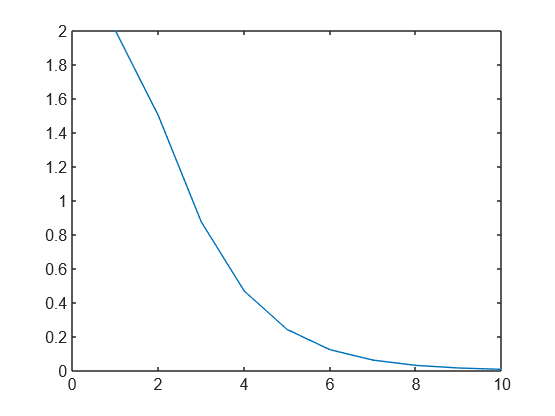

plot(yf1)

plot(yf2)

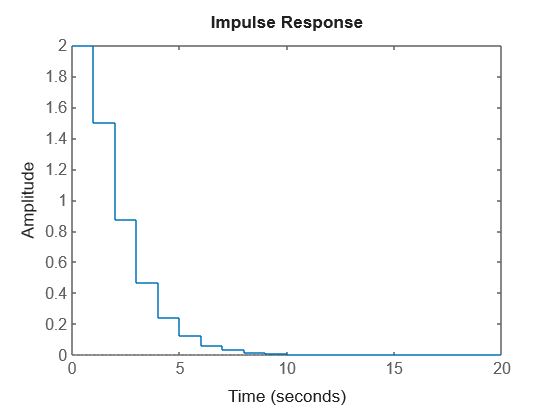

impulse(yf3) %impulso continuo em um sistema discreto

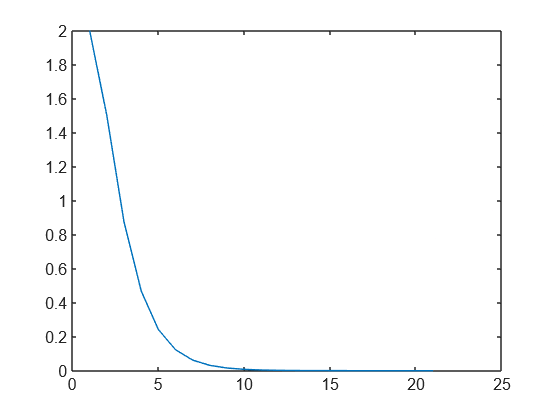

plot(yf4)

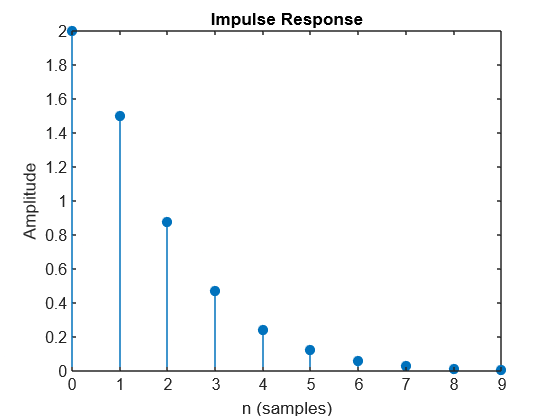

impz(2,[1 -3/4 1/8],0:9)